# Acrobot Perturbation Analysis: Rotations

This script computes the change of coordinates from $(q_u,p_u)$ coordinates into $(\mu,\alpha)$ coordinates for the oscillation area, where

- $\mu = \text{sign}(p_u)\sqrt{p_u^2 +30m^2gl^3(1-cos(q_u))}$ for 

- 
$$\alpha = q_u$$


- 
$$q_u = \alpha$$


- 
$$p_u = \text{sign}(\mu)\sqrt{\mu^2 -30m^2gl^3(1-cos(\alpha))}$$


We apply this to the constrained dynamics under the VNHC $q_a = \bar{q}_a\arctan(I p_u)$ and compute the nominal dynamics under $I = 0$. 

Then (for $I \neq 0$) we scale time to get $\dot{\hat{\mu}} = \frac{\dot{\mu}}{\dot{\alpha}} =: g(\alpha,\hat{\mu},I)$ and perform a perturbation analysis to find $\hat{\mu}(\alpha) \approx \hat{\mu}_0(\alpha) + I \hat{\mu}_1(\alpha)$, where $\hat{\mu}_0(\alpha)$ is the solution to the ODE $\dot{z}_0 = g(\alpha,z_0,0)$ and $\hat{\mu}_1(\alpha)$ is the solution to the ODE $\dot{z}_1 = \frac{\partial g}{\partial \alpha}(\alpha, \hat{\mu}_0(\alpha), 0)z_1 + \frac{\partial g}{\partial I}(\alpha, \hat{\mu}_0(\alpha), 0)$.

clear all
close all
clc;

% Set the dynamic variables for the acrobot
m = sym('m','positive'); % mass
g = sym('g','positive'); % gravity
l = sym('l','positive'); % length
I = sym('I','real'); % VNHC parameter
qb = sym('Q','positive'); % VNHC gain parameter
% Define our coordinates
mu = sym('u','real'); % pseudo-radius, in ]0,pi[
assumeAlso(mu^2 > 60*m^2*g*l^3);
alpha = sym('a','real'); % pseudo-angle, in ]-pi,pi]
assumeAlso(-pi < alpha);
assumeAlso(alpha <= pi);
q = sym('q','real'); % unactuated shoulder angle, in ]-pi,pi]
assumeAlso(-pi < q);
assumeAlso(q <= pi);
p = sym('p','real'); % unactauted momentum

% Set (qu,pu) as functions of (alpha,mu)
qu = alpha;
pu = sign(mu)*...
    sqrt(mu^2-30*m^2*g*l^3*(1-cos(alpha)));

% Set the actuator symbolically
qa = qb*atan(I*pu);

% Compute the dynamics (qud,pud) as functions of (mu,alpha)
Ipu1 = simplify((1+I^2*pu^2));
su = sin(qu);
sua = sin(qu + qa);
ca = cos(qa);
su2sua = simplify(2*su + sua);
m2gl3 = m^2*g*l^3;

qud = simplify(...
    simplify((Ipu1*pu + m2gl3*qb*I*su2sua*(1+ca))) / ...
    simplify((m*l^2*Ipu1*(3+2*cos(qa)))) ...
    );
pud = simplify(-m*g*l*su2sua);

% Compute mu as a function of qu,pu
% This has a sign(pu) in front, which we ignore until
% after the derivative to avoid symbolic errors
muqp = sqrt(p^2+30*m^2*g*l^3*(1-cos(q)));
% Compute alpha as a function of qu,pu
alphaqp = q; 

% Compute the dynamcics (mud,alphad)
dmuq = simplify(subs(sign(p)*diff(muqp,q),[q p], [qu pu]));
dmup = simplify(subs(sign(p)*diff(muqp,p),[q p], [qu pu]));
daq = simplify(subs(diff(alphaqp,q),[q p],[qu pu]));
dap = simplify(subs(diff(alphaqp,p),[q p],[qu pu]));

mud = simplify([dmuq dmup]*[qud;pud]);
alphad = simplify([daq dap]*[qud; pud]);

% Reduce by setting I = 0
mud_nom = simplify(subs(mud,I,0));
alphad_nom = subs(alphad,I,0);

% Scale the time and resubstitute to find our function g
gfun = simplify(mud / alphad);

% Get the ODE for mu_1
gdu = simplify(subs(diff(gfun,mu),I,0));
gdI = simplify(subs(diff(gfun,I),I,0));
% Fix simplification errors
symsToSimplify = [sign(mu*...
    (mu^2 - 30*g*l^3*m^2 + 30*g*l^3*m^2*cos(alpha))^(1/2))];
simplifiedValues = [sign(mu)];
gdI = simplify(subs(gdI, symsToSimplify, simplifiedValues));
% Assign values to m, g, l, qbar.
gdI = simplify(subs(gdI,[m g l qb], [1 1 1 1]));
gdIf = matlabFunction(gdI,'vars',[alpha mu]);

% The integral of gdu*x1 + gdI from alpha = -pi:pi 
% gives us the increase in mu across rotations when
% mu is positive.
% Note that gdu = 0, so we can ignore it, and for
% [m g l qb] = [1 1 1 1] rotations occur at |mu| > sqrt(60).
mu0splus = linspace(8,100,100);
u1plus = zeros(size(mu0splus));
for i = 1:length(mu0splus)
    mu0 = mu0splus(i);
    u1plus(i) = integral(@(t)gdIf(t,mu0),-pi,pi);
end
% Likewise, the integral from alpha = pi:-pi gives us the
% change in mu across rotations when mu is negative.
mu0sneg = -flip(mu0splus);
u1neg = zeros(size(mu0sneg));
for i = 1:length(mu0sneg)
    mu0 = mu0sneg(i);
    u1neg(i) = integral(@(t)gdIf(t,mu0),pi,-pi);
end

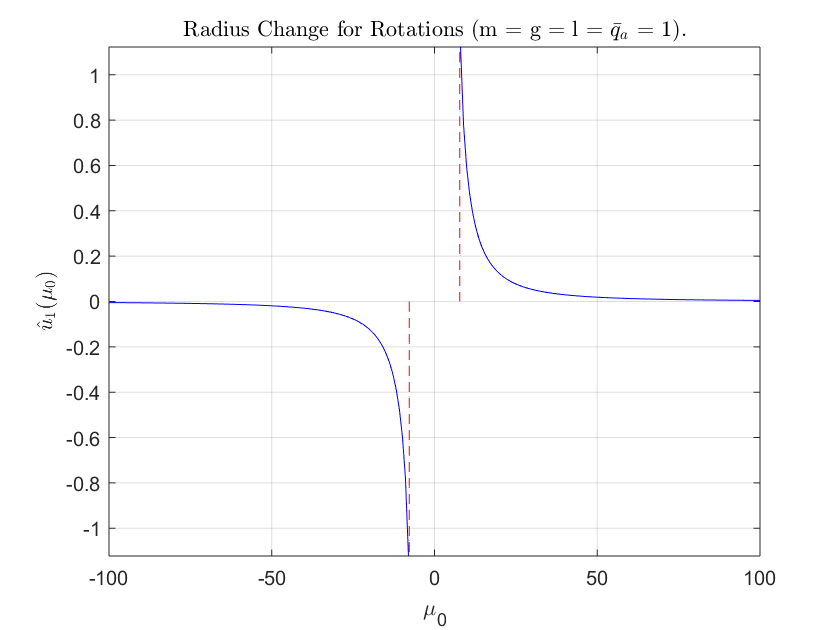

% Display u1(mu) and a vertical red dashed line at |mu|=sqrt(60)
sqrt60lineplus = linspace(0,u1plus(1),100);
sqrt60lineneg = linspace(0,u1neg(end),100);
sqrt60s = ones(size(sqrt60lineplus)).*sqrt(60);
u1fig = figure;
plot(mu0splus,u1plus,'b',...
    sqrt60s,sqrt60lineplus,'r--',...
    mu0sneg,u1neg,'b',...
    -sqrt60s,sqrt60lineneg,'r--');
ylim([u1neg(end),u1plus(1)]);
grid on;
title('Radius Change for Rotations (m = g = l = $$\bar{q}_a$$ = 1).',...
    'Interpreter','latex');
xlabel('\mu_0');
ylabel('$$\hat{u}_1(\mu_0)$$','interpreter','latex');


% Save the file to the folder images/Qmu.png
fname = fullfile(pwd,'thesis_sims','images','u1Rot.png');
saveas(u1fig,fname);